# Semplice Esempio: Stima della temperatura

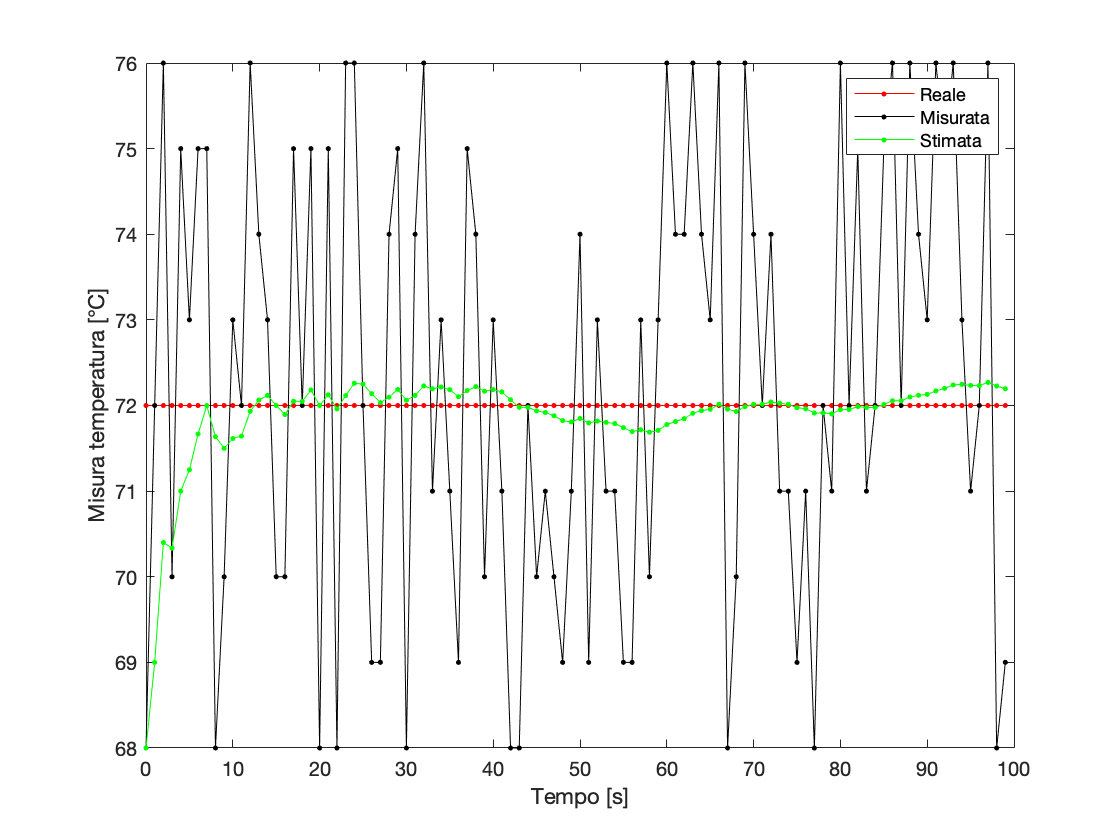

stima_iniziale = 68;
errore_stima = 2;
misura_iniziale = 75;
errore_misura = 4;
stima_precendete = stima_iniziale;
valore_reale = 72;
t = [];
misura = [];
stima = [];
reale = [];
for i = 1:100
    t(i)=i-1;
    misura(i) = 72 + randi([-4, 4]);
    KG = errore_stima/(errore_stima+errore_misura);
    stima(i) = stima_precendete+KG*[misura(i)-stima_precendete];
    errore_precedente = errore_stima;
    errore_stima = [1-KG]*errore_precedente;
    stima_precendete = stima(i);
    reale(i) = valore_reale;
end
plot(t,reale,'r.-',t,misura,'k.-',t,stima,'g.-');
legend('Reale','Misurata','Stimata');
xlabel("Tempo [s]");
ylabel("Misura temperatura [°C]");

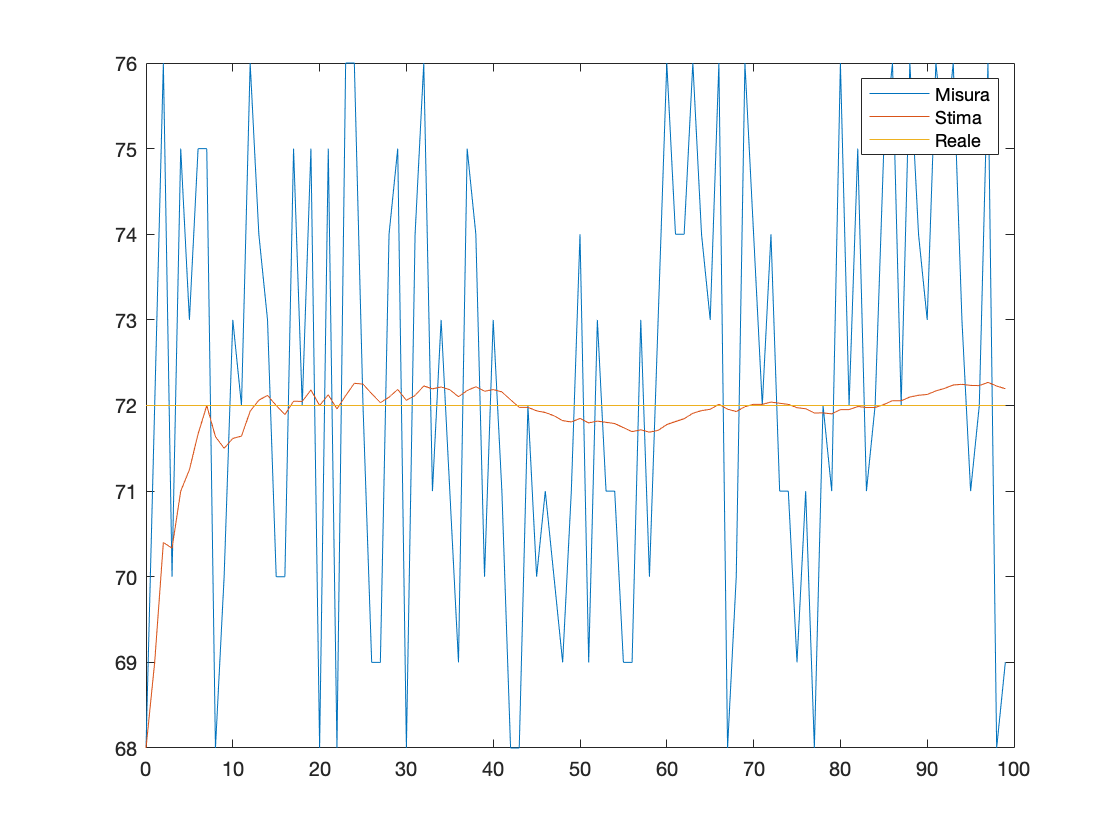

plot(t,misura,'DisplayName','Misura'),hold on
plot(t,stima,'DisplayName','Stima'),hold on
plot(t,reale,'DisplayName','Reale'),hold off
legend